Problem 1

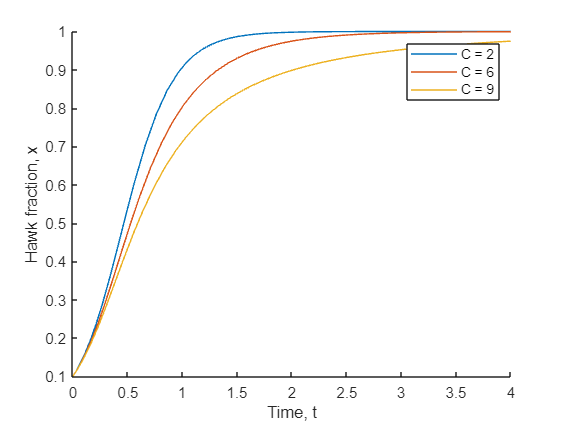

pars.G=10;
pars.C = [2 6 9];
pars.x0=0.1; 
pars.tmax=4;
figure();
hold on;
for i = 1:length(pars.C)
    pars.A=[(pars.G-pars.C(i))/2 pars.G; 0 pars.G/2];
    [t,x]=ode45(@hd_model,[0 pars.tmax],pars.x0,[],pars);
    plot(t,x);
end
xlabel('Time, t');
ylabel('Hawk fraction, x');
legend('C = 2', 'C = 6', 'C = 9');
hold off;

Problem 2

pars1.G=10;
pars1.C = 16;
disp('Expected Equilibrium: 10/16 = .625')

Expected Equilibrium: 10/16 = .625


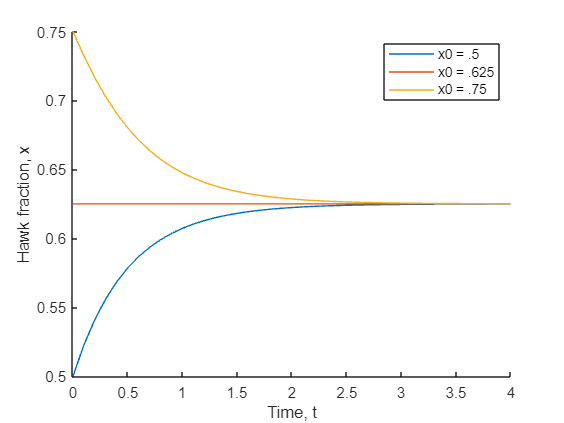

pars1.x0 = [.5 .625 .75];
pars1.A=[(pars1.G-pars1.C)/2 pars1.G; 0 pars1.G/2];
pars1.tmax=4;
figure();
hold on;
for i = 1:length(pars1.x0)
    [t,x]=ode45(@hd_model,[0 pars1.tmax],pars1.x0(i),[],pars1);
    plot(t,x);
end
xlabel('Time, t');
ylabel('Hawk fraction, x');
legend('x0 = .5', 'x0 = .625', 'x0 = .75');
hold off;

Functions

function dxdt = hd_model(t,x,pars)
r1=x*pars.A(1,1)+(1-x)*pars.A(1,2);
r2=x*pars.A(2,1)+(1-x)*pars.A(2,2);
r_avg = r1*x+r2*(1-x);
dxdt = r1*x-r_avg*x;
end